# Example 5.1: Frequency Hopping Signal Detection

Nicholas O'Donoughue 1 July 2019

*Consider a frequency hopping communications signal with a hop rate of *$$f_{\mathrm{hop}}=100$$* hops/s (*$$T_{\mathrm{hop}}=10$$* ms), instantaneous bandwidth of *$$B_t = 5$$* MHz, and hopping bandwidth of *$$B_{\mathrm{hop}}=200$$* MHz.*

*If we assume that the receiver's bandwidth is equal to the signal bandwidth (*$$B_r = 5$$* MHz), and that we want to scan the entire channel at least once per hop to detect the signal, how long can we dwell on each channel, and what probability of detection is achievable (assuming a maximum acceptable *$$P_{\mathrm{FA}}$$* of *$$10^{-6}$$*)?*

## Solution

We begin by defining the scan variables and computing how many different frequencies must be sampled to scan the entire hopping bandwidth.


$$N_\mathrm{chan} = \left\lfloor \frac{B_{\mathrm{hop}}}{B_{r}}\right\rfloor$$


% Scan Variables
Thop = [0.01, 0.001, 0.0001]; % Target signal hopping period [s]
Bhop = 200000000; % Target signal hopping bandwidth
Bs = 5000000;     % Target signal transmit bandwidth
Br = 5000000;    % Target signal receive bandwidth

Nchan = floor(Bhop/Br)

Nchan = 40

and compute the available time for each frequency sample, or dwell, within the scan


$$T_{\mathrm{dwell}} = \frac{T_{\mathrm{hop}}}{N_{\mathrm{chan}}}$$


Tdwell = Thop./Nchan

Tdwell = 	1.0e+-3 *

    0.2500    0.0250    0.0025


At the sampling rate of 5 MHz, each frequency sample will contain M=1,250 samples.

fs = Br;
M = floor(Tdwell*fs)

M =         1250         125          12


 This detection curve is shown below (solid line). To achieve a detection probability of, say 90%,  requires SNR of $$\xi \geq -7.4$$ dB. If, instead, the signal hops at a rate of $$f_{\mathrm{hop}}$$=1,000 hops/sec (dashed line) or 10,000 hops/sec (dotted line), as some modern military datalinks do, similar detection performance would require SNR levels of $$\xi \geq -1.8$$ dB or 4.7 dB, respectively.

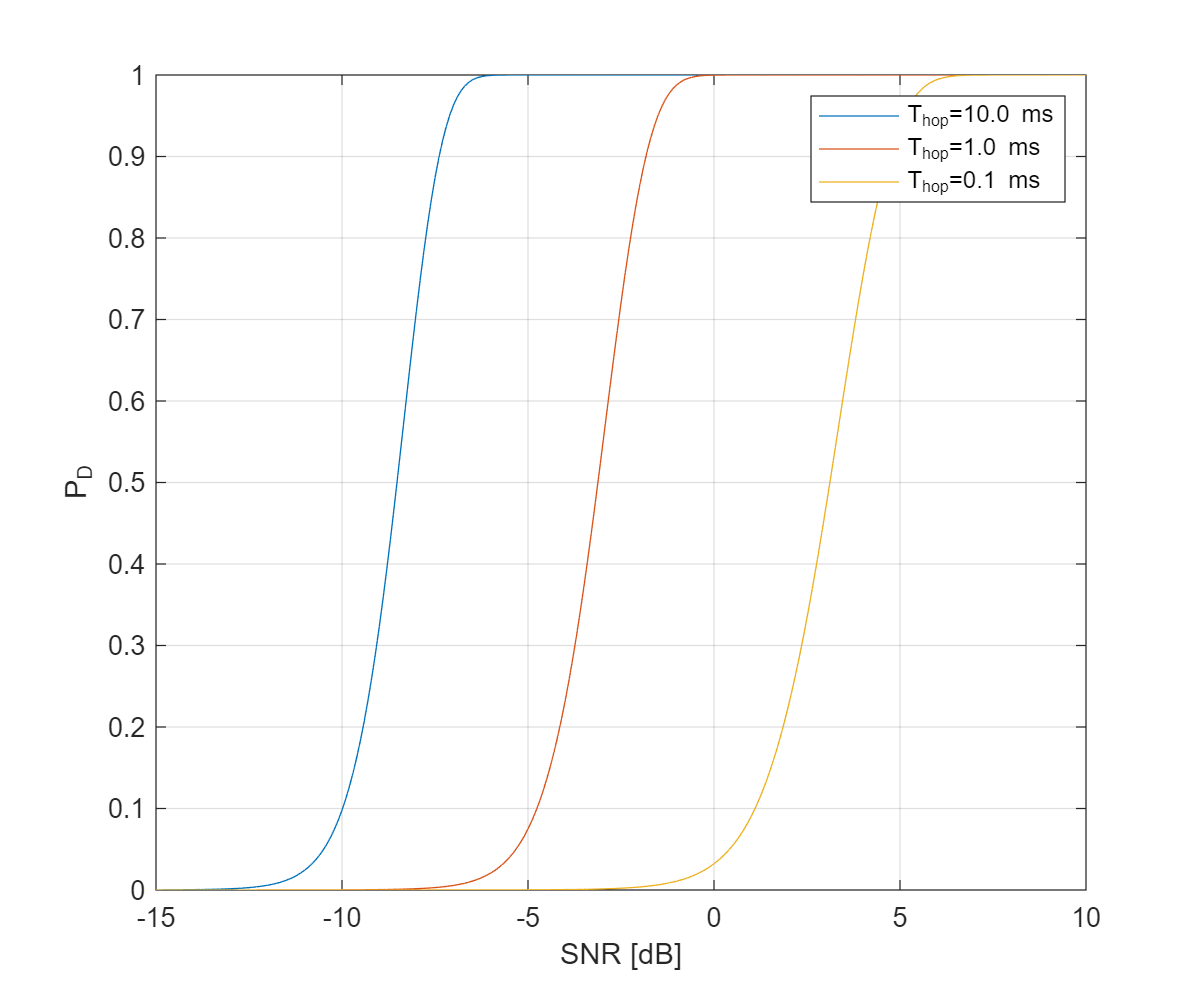

% Check for existence of Statistics & Machine Learning Toolbox
use_stat_toolbox = license('test','Statistics_Toolbox');
   % If TRUE, then built-in functions will be used.
   % If FALSE, then custom-builts replacements in the utils namespace will
   % be used.

% Detection Curve
xi_min_db = -15;
xi_max_db = 10;
xi_step = 0.1;
xi_db_vec = xi_min_db:xi_step:xi_max_db;
xi_lin_vec = 10.^(xi_db_vec/10);
PFA = 1e-6;

[XI,MM] = ndgrid(xi_lin_vec,M);
if use_stat_toolbox
    eta = chi2inv(1-PFA,2*MM);
    PD = 1-ncx2cdf(eta,2*MM,2*MM.*XI);
else
    eta = utils.chi2inv(1-PFA,2*MM);
    PD = 1-ncx2cdf(eta,2*MM,2*MM.*XI);
end

fig=figure;
plot(xi_db_vec,PD);
xlabel('SNR [dB]');ylabel('P_D');
legend(arrayfun(@(x) sprintf('T_{hop}=%.1f ms',x),Thop*1e3,'UniformOutput',false));
grid on;

All of these curves assume that the only job of the detector is to find the hopping signal, not to perform any analysis. If countermeasures are required, such as jamming the signal as it hops, then the scan period must be a fraction of the hopping period, rather than equivalent to the full length.